复现卢卡斯书聚焦场，这里把原书的nθ基矢做了改变，看计算结果与原书结果的差别

clear
syms theta phi ex ey ez n1 n2
sigma = sqrt(n1/n2)*sqrt(theta);
Ei = [ex ey ez];
nphi = [-sin(phi) cos(phi) 0];
nrho = [cos(phi) sin(phi) 0];
ntheta = [-cos(theta)*cos(phi) -cos(theta)*sin(phi) sin(theta)];
einifit = Ei*nphi.'*nphi.'*sigma ...
    + Ei*nrho.'*ntheta.'*sigma

$$einifit = \begin{array}{l} \left(\begin{array}{c} -\sqrt{\theta }\,\sin\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\sigma_{2}-\sqrt{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\sigma_{1}\\ \sqrt{\theta }\,\cos\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\sigma_{2}-\sqrt{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\sigma_{1}\\ \sqrt{\theta }\,\sin\left(\theta \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\mathrm{ex}\,\cos\left(\varphi \right)+\mathrm{ey}\,\sin\left(\varphi \right)\\ \sigma_{2}=\mathrm{ey}\,\cos\left(\varphi \right)-\mathrm{ex}\,\sin\left(\varphi \right) \end{array}$$

Ex = simplify(einifit(1))

$$Ex = -\sqrt{\theta }\,\sin\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\left(\mathrm{ey}\,\cos\left(\varphi \right)-\mathrm{ex}\,\sin\left(\varphi \right)\right)-\sqrt{\theta }\,\cos\left(\varphi \right)\,\cos\left(\theta \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\left(\mathrm{ex}\,\cos\left(\varphi \right)+\mathrm{ey}\,\sin\left(\varphi \right)\right)$$

Ey = simplify(einifit(2))

$$Ey = \sqrt{\theta }\,\cos\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\left(\mathrm{ey}\,\cos\left(\varphi \right)-\mathrm{ex}\,\sin\left(\varphi \right)\right)-\sqrt{\theta }\,\cos\left(\theta \right)\,\sin\left(\varphi \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\left(\mathrm{ex}\,\cos\left(\varphi \right)+\mathrm{ey}\,\sin\left(\varphi \right)\right)$$

Ez = simplify(einifit(3))

$$Ez = \sqrt{\theta }\,\sin\left(\theta \right)\,\sqrt{\frac{n_{1}}{n_{2}}}\,\left(\mathrm{ex}\,\cos\left(\varphi \right)+\mathrm{ey}\,\sin\left(\varphi \right)\right)$$

% 
% syms theta phi ex ey ez n1 n2
% sigma(theta) = sqrt(n1/n2)*sqrt(theta);
% Ei = [ex ey ez];
% nphi(phi) = [-sin(phi) cos(phi) 0];
% nrho(phi) = [cos(phi) sin(phi) 0];
% ntheta(theta,phi) = [-cos(theta)*cos(phi) -cos(theta)*sin(phi) sin(theta)];
% einifit(theta,phi) = Ei*nphi(phi).'*nphi(phi).'*sigma(theta) ...
%     + Ei*nrho(phi).'*ntheta(theta,phi).'*sigma(theta);
% Ex = einifit(1)
% E_ = matlabFunction(einifit);


## 我的计算结果

这里假设nθ的取向是最朴素的想法，看起来怎么样就是怎么样的

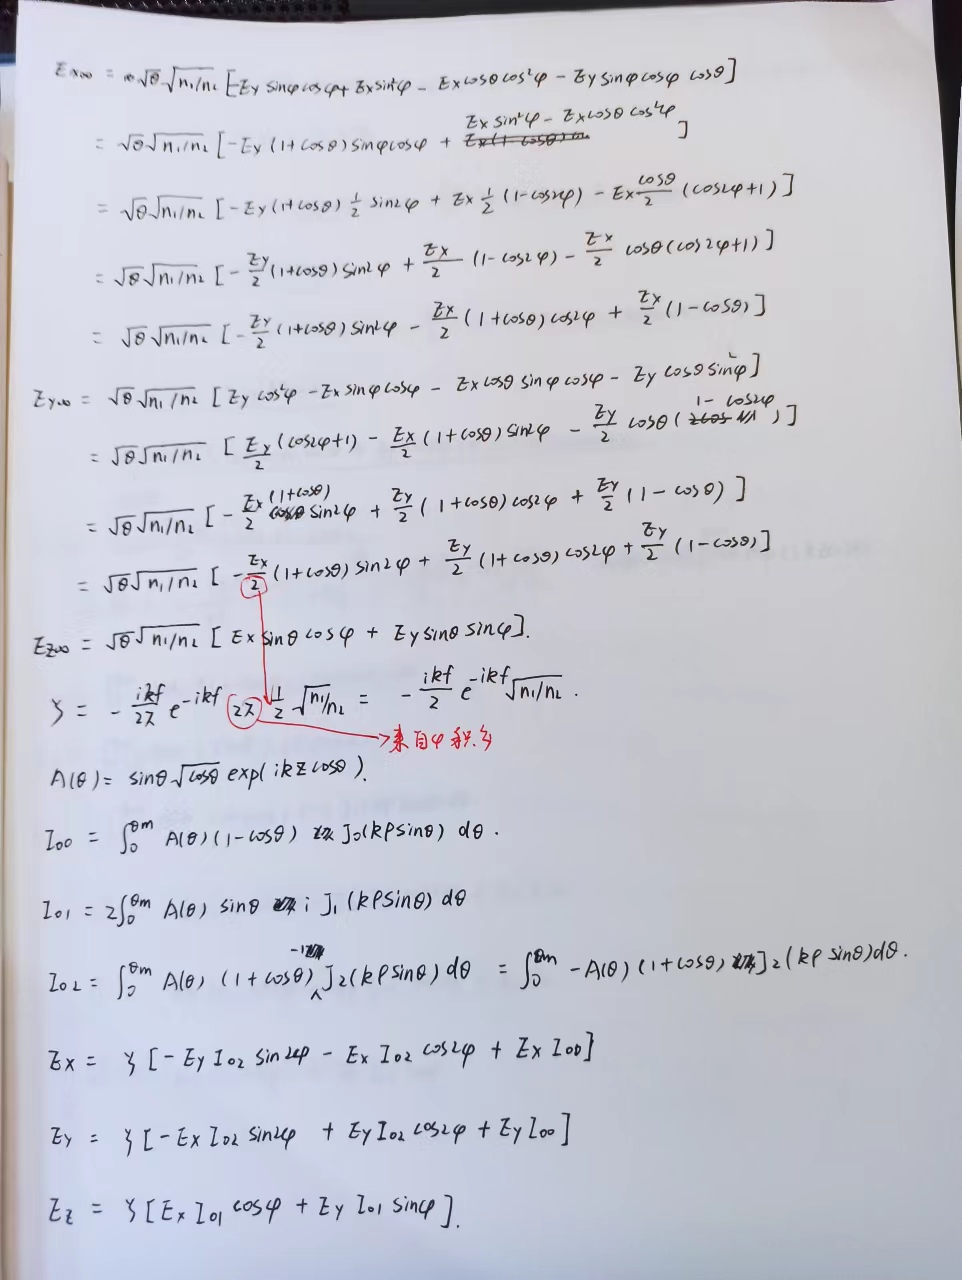

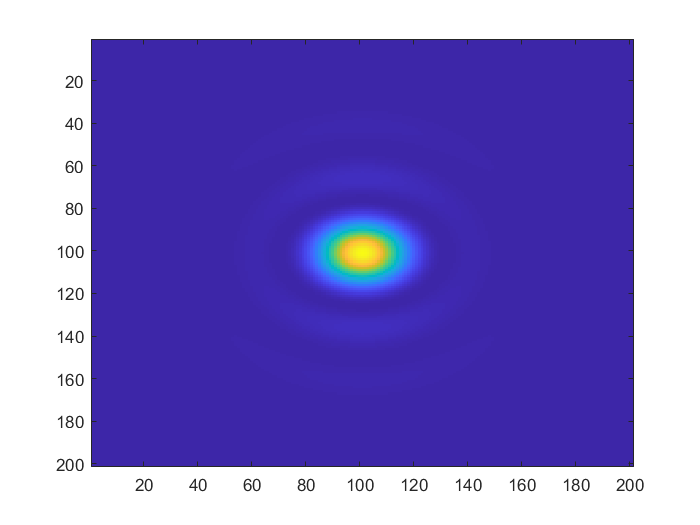

lambda = 670*1e-9;
k0 = 2*pi/lambda;
n1 = 1;
n2 = 1.518;
NA = 1.45;
thetamax = asin(NA/n2);
k2 = n2*k0;
f = 1e-4;
z = 0;
ksi = -i*k2*f/2*sqrt(n1/n2)*exp(-i*k2*f);
ex = 1;
ey = 0;
ez = 0;

x = (-1:0.01:1)*1e-6;
y = x;
[x,y] = meshgrid(x,y);
[phi,rho] = cart2pol(x,y);

A = @(theta) sin(theta).*sqrt(cos(theta)).*exp(i/k2*z*cos(theta));
% result by myself
% f00 = @(theta) A(theta).*(1-cos(theta)).*besselj(0,k2*rho.*sin(theta));
% f01 = @(theta) 2*i*A(theta).*sin(theta).*besselj(1,k2*rho.*sin(theta));
% f02 = @(theta) -A(theta).*(1+cos(theta)).*besselj(2,k2*rho.*sin(theta));
% result of book
f00 = @(theta) A(theta).*(1+cos(theta)).*besselj(0,k2*rho.*sin(theta)); 
f01 = @(theta) -2*i*A(theta).*sin(theta).*besselj(1,k2*rho.*sin(theta));
f02 = @(theta) -A(theta).*(1-cos(theta)).*besselj(2,k2*rho.*sin(theta));

I00 = integral(f00,0,thetamax,'ArrayValued',1);
I01 = integral(f01,0,thetamax,'ArrayValued',1);
I02 = integral(f02,0,thetamax,'ArrayValued',1);
Ex = ksi*(-ey*I02.*sin(2*phi) - ex*I02.*cos(2*phi) + ex*I00);
Ey = ksi*(-ex*I02.*sin(2*phi) + ey*I02.*cos(2*phi) + ey*I00);
Ez = ksi*(ex*I01.*cos(phi) + ey*I01.*sin(phi));
figure
imagesc(abs(Ex).^2);
caxis([0 2.9507e+05])

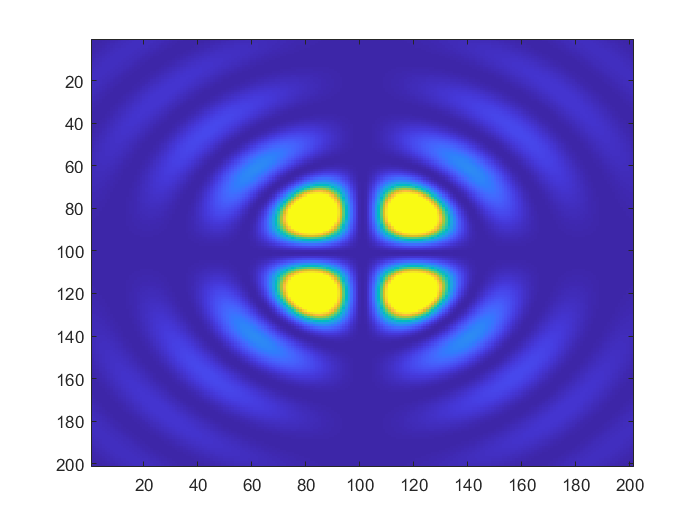

figure
imagesc(252*abs(Ey).^2);
caxis([0 2.9507e+05])

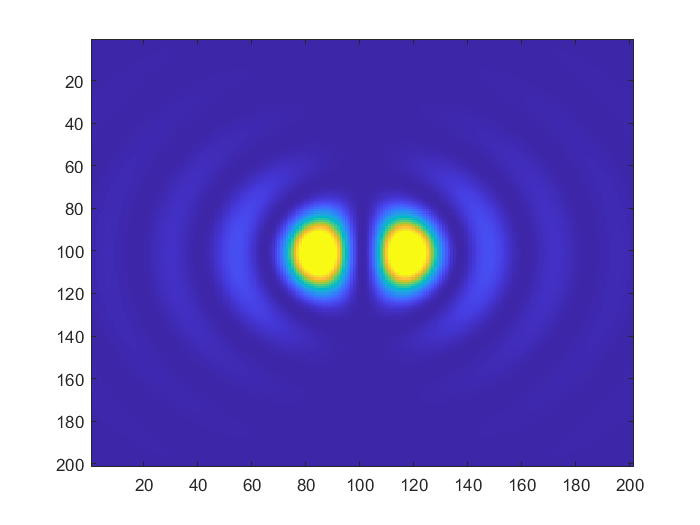

figure
imagesc(8*abs(Ez).^2);
caxis([0 2.9507e+05])